Call the Summary Table

LatexPlots
load SummTable_AG
% Delete Analysis for the Last scale factor
filter1 = find(SummTable.hazlvl <= 3);
%SummTable(filter1, :) = [];
SummTable_AG = SummTable(filter1,:);
load SummTable_OB_old
filter1 = find(SummTable.hazlvl <= 3);
SummTable_OB = SummTable(filter1, :)

SummTable_OB = 960×20 table
    hazlvl    cf       spd       bridgemodel     pga        pgv         pbd         pbv       pba        pbrot         pcd         pwd        pcrot        pwrot        purot        pcha      pcva     drdis      drcase    gm
    ______    __    _________    ___________    ______    _______    _________    _______    ______    __________    ________    ________    ________    _________    

Plot of PGA vs Derailments

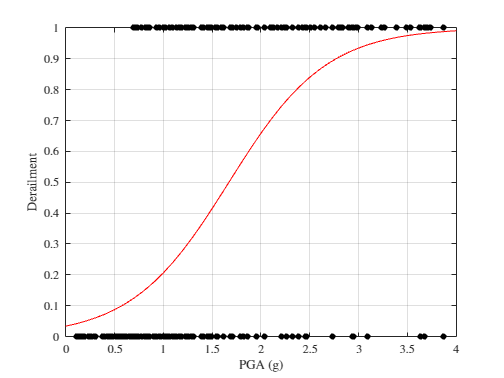

close
NotSortedData = [SummTable.pga/9.81, SummTable.drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.5;
winres = 0.01;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.1:4.0)';
ynew = predict(mdl, xnew);

plot(SummTable.pga/9.81, SummTable.drcase, 'k.', ...
    xnew, ynew, 'r', 'MarkerSize', 15.0), grid on, xlabel('PGA (g)'), ylabel('Derailment'), xlim([0, 4])

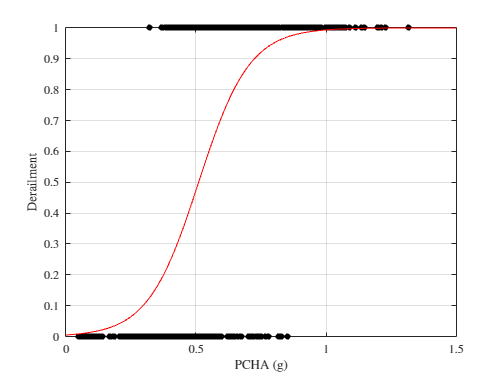

close
NotSortedData = [SummTable.pcha/9.81, SummTable.drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.02;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end


mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:1.5)';
ynew = predict(mdl, xnew);


plot(SummTable.pcha/9.81, SummTable.drcase, 'k.', ...
    xnew, ynew, 'r', 'MarkerSize', 15.0), grid on, xlabel('PCHA (g)'), ylabel('Derailment')

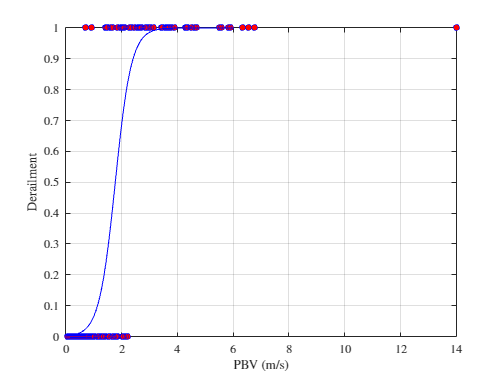

close
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
plot(SummTable(filter,:).pbv, SummTable(filter,:).drcase, 'r.', ...
    xnew, ynew, 'r', 'MarkerSize', 15.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:6.0)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(SummTable(filter, :).pbv, SummTable(filter, :).drcase, 'bo', ...
    xnew, ynew, 'b-', 'MarkerSize', 5.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')

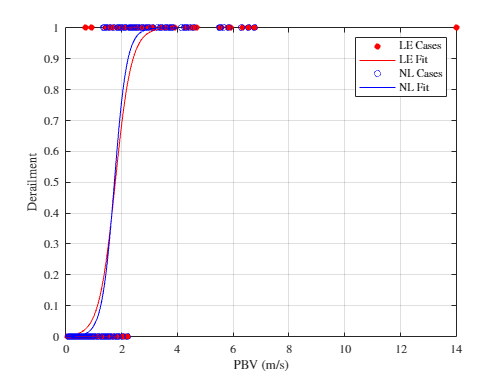

close
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
plot(SummTable(filter,:).pbv, SummTable(filter,:).drcase, 'r.', ...
    xnew, ynew, 'r', 'MarkerSize', 15.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(SummTable(filter, :).pbv, SummTable(filter, :).drcase, 'bo', ...
    xnew, ynew, 'b-', 'MarkerSize', 5.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
legend('Coupled Cases', 'Decoupled Fit', 'NL Cases', 'NL Fit')

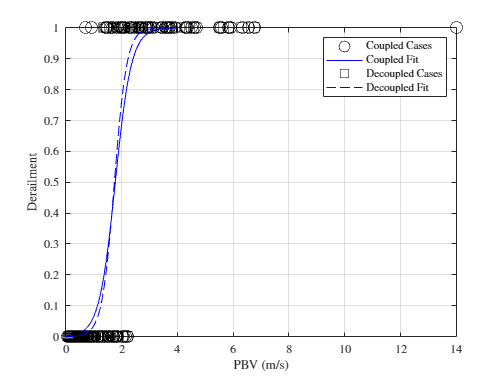

close
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
plot(SummTable(filter,:).pbv, SummTable(filter,:).drcase, 'ko', ...
    xnew, ynew, 'b-', 'MarkerSize', 10.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(SummTable(filter, :).pbv, SummTable(filter, :).drcase, 'ks', ...
    xnew, ynew, 'b--', 'MarkerSize', 10.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
legend('Coupled Cases', 'Coupled Fit', 'Decoupled Cases', 'Decoupled Fit')

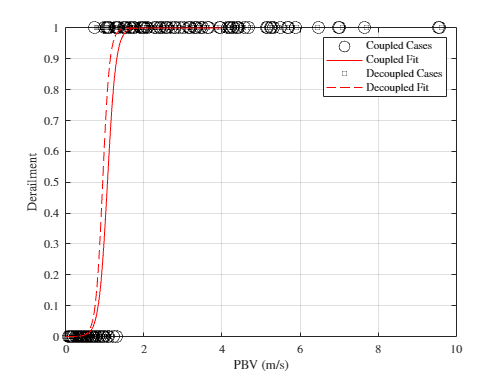

close
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
plot(SummTable(filter,:).pbv, SummTable(filter,:).drcase, 'ko', ...
    xnew, ynew, 'r-', 'MarkerSize', 10.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(SummTable(filter, :).pbv, SummTable(filter, :).drcase, 'ks', ...
    xnew, ynew, 'r--', 'MarkerSize', 5.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
legend('Coupled Cases', 'Coupled Fit', 'Decoupled Cases', 'Decoupled Fit')

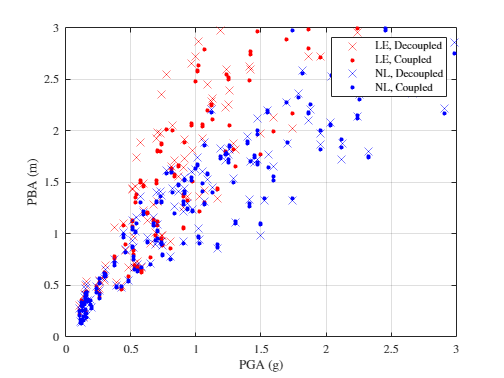

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled


plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pba/9.81, 'rx', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pba/9.81, 'r.', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pba/9.81, 'bx', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pba/9.81, 'b.','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PBA (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')

axis([0, 3, 0, 3])
grid on

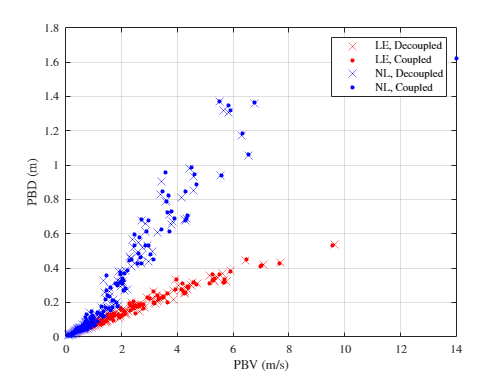

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled


plot(SummTable(indices1,:).pbv, SummTable(indices1,:).pbd, 'rx', ...
     SummTable(indices2,:).pbv, SummTable(indices2,:).pbd, 'r.', ...
     SummTable(indices3,:).pbv, SummTable(indices3,:).pbd, 'bx', ...
     SummTable(indices4,:).pbv, SummTable(indices4,:).pbd, 'b.','MarkerSize', 10.0)

xlabel('PBV (m/s)'), ylabel('PBD (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')

%axis([0, 3, 0, 3])
grid on

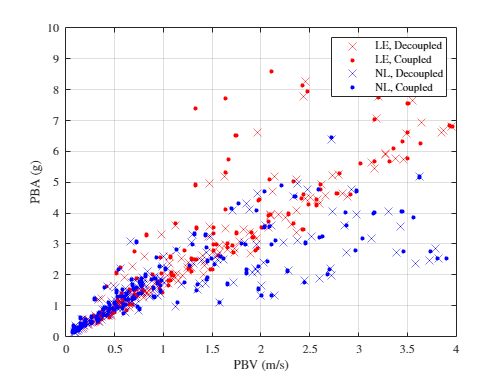

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled


plot(SummTable(indices1,:).pbv, SummTable(indices1,:).pba/9.81, 'rx', ...
     SummTable(indices2,:).pbv, SummTable(indices2,:).pba/9.81, 'r.', ...
     SummTable(indices3,:).pbv, SummTable(indices3,:).pba/9.81, 'bx', ...
     SummTable(indices4,:).pbv, SummTable(indices4,:).pba/9.81, 'b.','MarkerSize', 10.0)

xlabel('PBV (m/s)'), ylabel('PBA (g)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')

axis([0, 4, 0, 10])
grid on

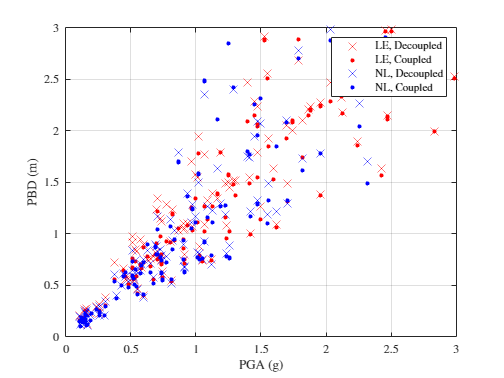

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled


plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pbd / 6 * 100, 'rx', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pbd / 6 * 100, 'r.', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pbd / 6 * 100, 'bx', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pbd / 6 * 100, 'b.','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PBD (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')


axis([0, 3, 0, 3])
grid on

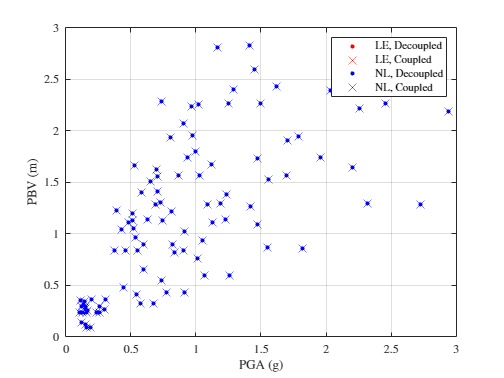

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled

plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pgv, 'r.', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pgv, 'rx', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pgv, 'b.', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pgv, 'bx','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PBV (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')


axis([0, 3, 0, 3])
grid on

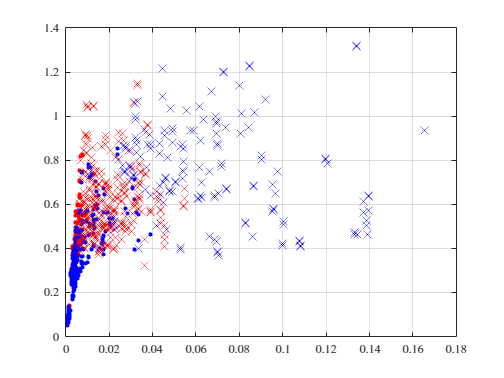

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 1.0));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0));  % Nonlinear, Coupled
plot(SummTable(indices1,:).pbd/9.81, SummTable(indices1,:).pcha/9.81, 'r.', ...
     SummTable(indices2,:).pbd/9.81, SummTable(indices2,:).pcha/9.81, 'b.', ...
     SummTable(indices3,:).pbd/9.81, SummTable(indices3,:).pcha/9.81, 'rx', ...
     SummTable(indices4,:).pbd/9.81, SummTable(indices4,:).pcha/9.81, 'bx','MarkerSize', 10.0)
grid on

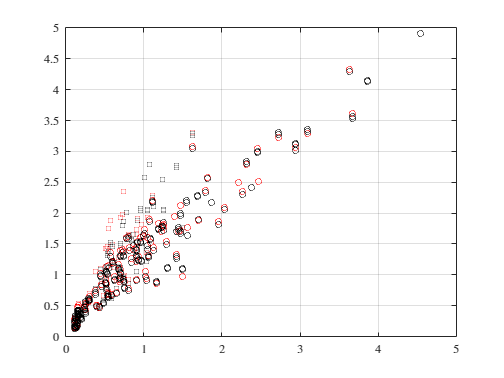

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled
plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pba/9.81, 'rs', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pba/9.81, 'ro', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pba/9.81, 'ks', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pba/9.81, 'ko','MarkerSize', 5.0), grid

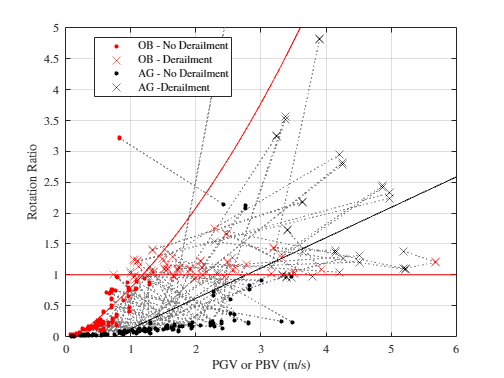

close all
cfac = 1.0;
indices1 = find((SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, No derail
indices2 = find((SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, Derail
indices3 = find((SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 0.0).*(SummTable_AG.cf == cfac));  % Linear Elastic, Coupled
indices4 = find((SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 1.0).*(SummTable_AG.cf == cfac));  % Nonlinear, Coupled

indices5 = find((SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.cf == cfac));
indices6 = find((SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.cf == cfac));


peakrot = deg2rad(0.836);

pfit1 = polyfit(SummTable_OB(indices1,:).pbv, SummTable_OB(indices1,:).purot, 2);
pfit2 = polyfit(SummTable_AG(indices3,:).pgv, SummTable_AG(indices3,:).purot, 1);

for i = 1:length(indices6)
    plot([SummTable_OB(indices5(i),:).pbv, SummTable_AG(indices6(i),:).pgv], [SummTable_OB(indices5(i),:).purot, SummTable_AG(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.5, 0.5, 0.5]), hold on
end

plot(SummTable_OB(indices1,:).pbv, SummTable_OB(indices1,:).purot/peakrot, 'r.', ...
     SummTable_OB(indices2,:).pbv, SummTable_OB(indices2,:).purot/peakrot, 'rx', ...
     SummTable_AG(indices3,:).pgv, SummTable_AG(indices3,:).purot/peakrot, 'k.', ...
     SummTable_AG(indices4,:).pgv, SummTable_AG(indices4,:).purot/peakrot, 'kx', 'MarkerSize', 10.0), hold on
xvals = 0:0.001:6.0;
plot(xvals, polyval(pfit1, xvals)/peakrot, 'r', ...
     xvals, polyval(pfit2, xvals)/peakrot, 'k', ...
     xvals, ones(1, length(xvals)), 'r'), axis([0 6.0 0 5.0])

grid, legend('OB - No Derailment', 'OB - Derailment','AG - No Derailment', 'AG -Derailment', Location='best'), xlabel('PGV or PBV (m/s)'), ylabel('Rotation Ratio')

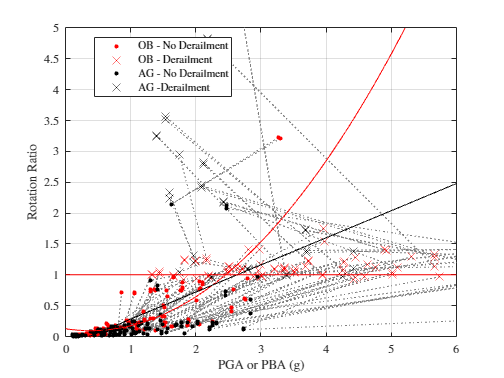

close all
cfac = 1.0;
indices1 = find((SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 0.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, No derail
indices2 = find((SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.drcase == 1.0).*(SummTable_OB.cf == cfac));  % Over Bridge, Coupled, Nonlinear, Derail
indices3 = find((SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 0.0).*(SummTable_AG.cf == cfac));  % Linear Elastic, Coupled
indices4 = find((SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.drcase == 1.0).*(SummTable_AG.cf == cfac));  % Nonlinear, Coupled

indices5 = find((SummTable_OB.bridgemodel == 0.0).*(SummTable_OB.cf == cfac));
indices6 = find((SummTable_AG.bridgemodel == 1.0).*(SummTable_AG.cf == cfac));


peakrot = deg2rad(0.836);

pfit1 = polyfit(SummTable_OB(indices1,:).pba/9.81, SummTable_OB(indices1,:).purot, 2);
pfit2 = polyfit(SummTable_AG(indices3,:).pga/9.81, SummTable_AG(indices3,:).purot, 1);

for i = 1:length(indices6)
    plot([SummTable_OB(indices5(i),:).pba, SummTable_AG(indices6(i),:).pga]/9.81, [SummTable_OB(indices5(i),:).purot, SummTable_AG(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.5, 0.5, 0.5]), hold on
end

plot(SummTable_OB(indices1,:).pba/9.81, SummTable_OB(indices1,:).purot/peakrot, 'r.', ...
     SummTable_OB(indices2,:).pba/9.81, SummTable_OB(indices2,:).purot/peakrot, 'rx', ...
     SummTable_AG(indices3,:).pga/9.81, SummTable_AG(indices3,:).purot/peakrot, 'k.', ...
     SummTable_AG(indices4,:).pga/9.81, SummTable_AG(indices4,:).purot/peakrot, 'kx', 'MarkerSize', 10.0), hold on
xvals = 0:0.001:6.0;
plot(xvals, polyval(pfit1, xvals)/peakrot, 'r', ...
     xvals, polyval(pfit2, xvals)/peakrot, 'k', ...
     xvals, ones(1, length(xvals)), 'r'), axis([0 6.0 0 5.0])

grid, legend('OB - No Derailment', 'OB - Derailment','AG - No Derailment', 'AG -Derailment', Location='best'), xlabel('PGA or PBA (g)'), ylabel('Rotation Ratio')